# RVC 1, Ch 7.2 Forward Kinematics

clear 
close all
clc
clear livescript

## Lec 04.2 (Ch 7.2) - A Very Simple 1DoF Robot

Serial link chains (i.e. links that are connected via joints to form arms) are formed of links and joints. 

In our 1 degree of freedom (a.k.a only 1 joint) example, consider a single link `a1` of length 1m and a joint that is controlled by a motor set to an angle of 0.2 radians as shown in the image below:

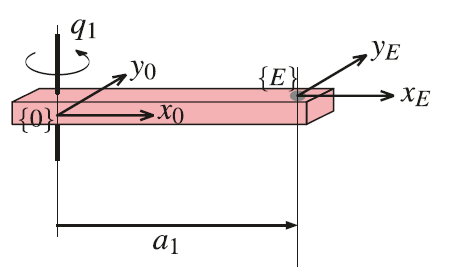

a1 = 1 % Length of link a1
q1 = 0.2 % Angle of joing q1

If we want to find the pose {E} of the end-effector of the robot arm (i.e. the tip of the robot that will interact with the world), we would have to compute that pose via the following two compounded transformations:

T1 = trot2(q1)*transl2(a1,0)

Take some time to analyze the output:

- The end-effector pose is set at an orientation defined by the 2x2 rotation matrix and is fixed as a function of `q1`. You also have the location of the end-effector pose set by the translation vector on the 3rd column.

### SE2 Generation

An SE2 object would allow us to pull these out easily:

T2 = SE2(rot2(q1)) * SE2(rot2(0), [a1,0])

T2.R
T2.t

This process is known as **Forward Kinematics**. It is the mapping from joint coordinates (or robot configuration) to an end-effector pose. 

### ETS2 Elementary Transform Sequence

ETS2 is a class rich in methods to analyize forward kinematics and many other properties of the serial link robot chain. The bulk of a robot’s physical structure is due to its links and these dictate its shape and appearance, as well as having important properties such as mass, inertia, and collision potential.

Considering the sequence of compound pose operations to describe the end-effector: 

ETS2 is actually a python module (a library of methods, like a matlab script). To use it in matlab, matlab has an 'import' method to do this:

import ETS2.*

Once it has been imported, you will notice the object ETS2 is available to matlab along with methods for translation along (x,y): `Tx(), Ty()` and rotations about z: `Rz(). `

- Link values like `a1`, are floats, whilst

- Joints like` 'q1'` must be passed in as a string. The actual joint angle value will be provided later by you when you compute the arm pose for a given angle via forward kinematics.

As such, the pose can be constructed as follows:

a1 = 1;

E = Rz('q1')*Tx(a1)

You should produce a pose object of class ETS2 (it will also have .RZ() about any joints that have been assigned)

class(E)

You can also see the chain itself by calling the `display member:`

E.display

And the parameters by calling the `param member:`

E.param

Now we can compute specific poses that are associated with a given joint angle value q1. 

To this end, use the **forward kinematics** method on E `fkine(\theta)`:

E.fkine(0)      % pose when q1=0

E.fkine(pi/6)   % pose when q1=30 degrees

E.fkine(pi/4)   % pose when q1=45 degrees

E.fkine(pi/3)   % pose when q1=60 degrees

E.fkine(pi/2)    % pose when q1=90 degrees

### Interactive Tools

This class allows you to interact with the robot when you call method `teach. This method will create a GUI in 3D along with sliders for the joints and windows reporting position and orientaiton. `

E.teach

### Symbolic Computation

The above process can also be repeated for symbolic computations. Begin by listing all variables as symoblic:

syms a1 q1 real

Then, make sure you have imported ETS2.* and construct your chain:

import ETS2.*
E = Rz(q1)*Tx(a1)

After this, the `fkine `method can be called without any angle argument to display the symbolic representation for the FwdKins.

E.fkine()

**Note**:

- As of Jan 2024 a1 is showing with a conjugate declaration. I am investigating this. This should be a1 by itself.

- There is an alternative trchain2 command that produces the right symbolic answer, but I will not cover it here to keep the number of methods needed to be learned to a minimum.

## Lec 04.3 (Ch 7.2) - 2 DoF Robot

The 2DoF robot is an extension of the 1DoF robot. In this case, we have the following chain:

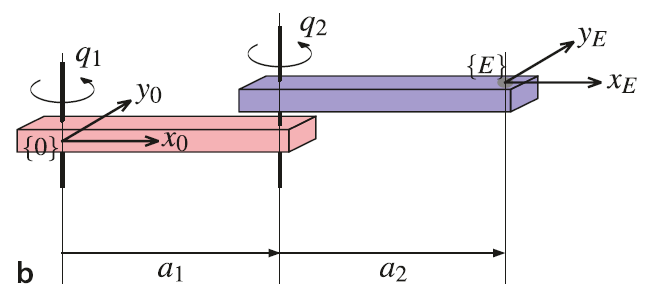

Considering the sequence of compound pose operations to describe the end-effector: 

We now define two links and their lengths:

a1 = 1;
a2 = 1;

Construct the pose with 2 joints 'q1','q2':

import ETS2.*
E = Rz('q1')*Tx(a1)*Rz('q2')*Tx(a2)

Analyze the class

class(E)

Analyze the chain:

E.display

Analyze the value of the parameters in the chain (a1,q1,a2,q2):

E.param

Use the forward kinematics method to compute the pose as a function of the two joint angles. 

Note, for multiple joint angles pass them in via square brackets: [q1,q2]

E.fkine([0,0])      % pose when q1=0

E.fkine([pi/2,0])   % pose when q1=30 degrees

E.fkine([0,pi/2])   % pose when q1=45 degrees

E.fkine([pi/2, pi/2])   % pose when q1=60 degrees

Interact with the 2 DoF robot by calling the teach command. Do this in the command window directly (highlight code + F9):

E.teach

In addition to these methods, let's explore a couple of other components of ETS2. 

If you would like to just plot the robot configuration without interacting use the `plot() `method with a vector of joint angle configurations [q1,q2]:

E.plot( [90, 45], 'deg' ) % shown in degrees instead of radians

Furthermore, if you did not know what the robot looked like and wanted to know the joint structure of the robot (the type of joints it uses in its chain), we can use the `structure` method:

E.structure

## Lec 04.4 (Ch 7.2) - 3 DoF Robot

The 3DoF robot is an extension of the 1DoF robot. In this case, we have the following chain:

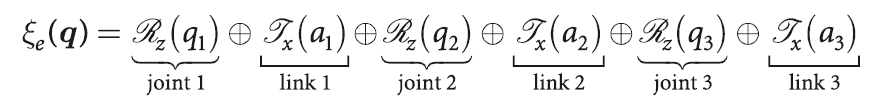

Symbolic

syms a1 a2 a3 q1 q2 q3 real
T3 = trchain2('R(q1) Tx(a1) Rz(q2) Tx(a2) Rz(q3) Tx(a3)', [q1, q2, q3] )

Notice how the symoblic expression is quite complex. 

To compute specific poses, use ETS2. 

Set the link names and lengths:

import ETS2.*
a1 = 1, a2 = 1, a3 = 1

Define the pose:

E = Rz('q1')*Tx(a1)*Rz('q2')*Tx(a2)*Rz('q3')*Tx(a3)

This time, as we have more angles, let's instead designate variables for your angles before calling the `fkine`method. You can then later vary these values here and call fkine again. 

q1 = 0; q2= pi/2; q3 = 0; 

Compute the pose:

T = E.fkine([q1,q2,q3])

Interact with the robot. Remember to call this from the command window by highlighting the command and pressing F9:

E.teach

## Lec 04.5 (Ch 7.2) - 3D Robot

In this section, we are now dealing with 3D robots that can translate across x,y,z space. 

In this section we will be introduce `ETS3` instead of ETS2. ETS3 now will include functions `Rx(), Ry(), Rz() and Tx(), Ty(), Tz()`.

Let's begin with a symbolic derivation of the Phantom X Pincher Robot Arm introduced in the lecture. 

The Phantom has 4 links: $a_1 - a_4$ and four joints: $q_1 - q_4$.

Create the symbolic variables:

syms a1 a2 a3 a4 q1 q2 q3 q4

Imported the ETS3.* module to construct your chain:

import ETS3.*
E = Rz(q1)*Tz(a1)*Ry(q2)*Tz(a2)*Ry(q3)*Tz(a3)*Ry(q4)*Tz(a4)

After this, the `fkine `method can be called without any angle argument to display the symbolic representation for the FwdKins.

E.fkine()

The expressions, as you can see, are significantly more complex.

## Lec 04.8 (Ch 7.2) - DH Parameterization via Revolute Joints and Serial Link Objects

As we saw, under the DH paradigm, the transformation from link coordiante frame {$j-1$}  to frame {$j$} is:

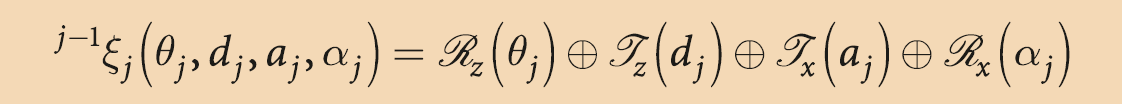

We can create a link with a revolute joint using the `Revolute`() method, which takes a link length as a string and the length of the link as a real:

L = Revolute('a',1)

L is an revolute-joint object of type Revolute:

class(L)

The `Revolute` class is a subclass of the generic **Link** class.

Once the revolute joint is created, we can compute the transformation between link frames for a given joint angle q as follows:

q1 = 0.5 % Set the value of the joint angle
T0 = L.A(q1) % Compute the transformation as SE3 object

Note the output is an SE3 object

class(T0)

The type of link can be extracted as follows:

L.type

And we can also extract the value of the link length as:

L.a

### Forward Kinematics via SerialLink

The forward kinematics of a generalized robot is then the composition of the relative pose due to each link:

where, 

- link 0 is the base of the robot (and commonly d1 = 0). 

- link N is the final link and carries the tool. 

We can connect two Link (or Revolute) objects together via the SerialLink class to create a simple 2 DoF robot with simple DH parameters. 

To do so, we will pass a vector of Revolute elements to the SerialLink method along with a pair of options: 'name', 'robot_name'.

robot = SerialLink( [ Revolute('a',1) Revolute('a', 1)], 'name', '2DoF' )

This instantiation create our 2DoF robot.

The forward kinematics can easily be computed using `fkine`(). Start by setting angles q1 and q2:

q1 = rand * (pi/2)

q2 = rand * (pi/2)

Then call fkine(q1,q2):

robot.fkine([q1,q2])

We can also plot the pose of the robot for a given joint angle configuration:

robot.plot([q1,q2])

### **Models**

In this section, we will explore pre-built robot models and their associated forward kinematics. 

In particular we will be interested in using the model for the Puma560 robot arm and the Panda arm used for the competition 

Puma Arm:

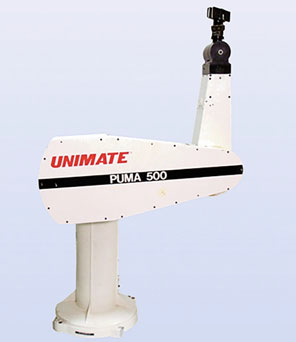

Panda Arm:

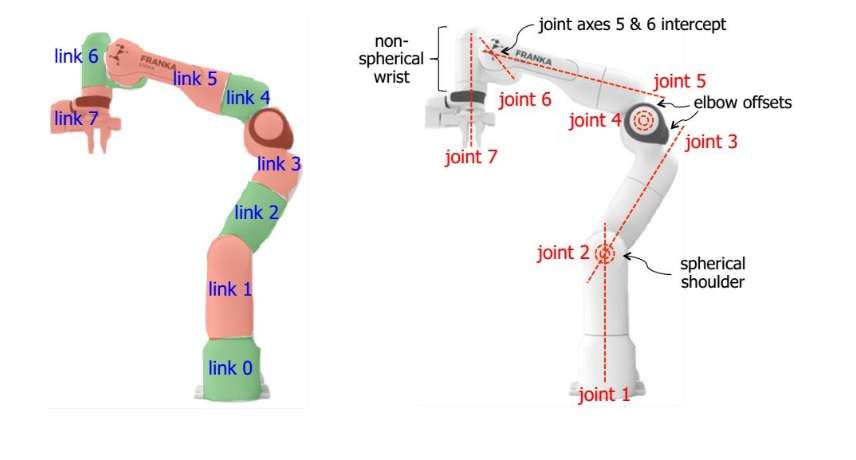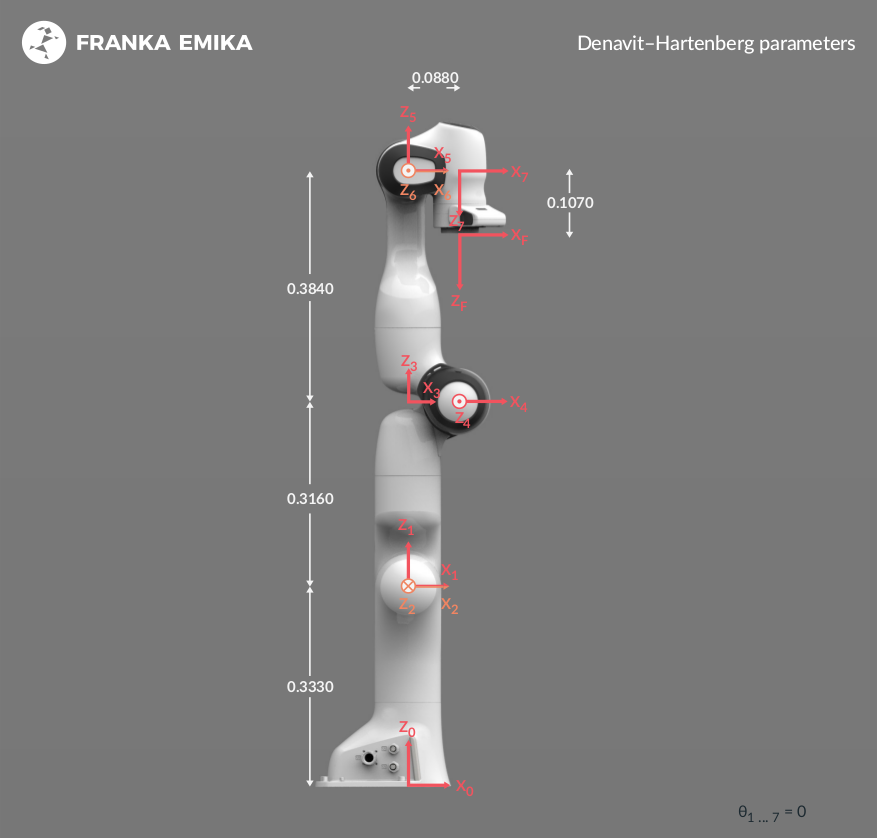

Also see the following link for more interesting information: 

[https://petercorke.com/robotics/franka-emika-panda-kinematics-and-singularities/](https://petercorke.com/robotics/franka-emika-panda-kinematics-and-singularities/) 

Before we get started, let's clear our workspace from all variables:

clear

The toolbox has modeled an extensive number of robots. A complete list can be seen by typing 'models':

models

### Puma 560 Model

Any of these models can be loaded directly by calling on their name. 

Names always start with 'mdl_' and follow with the name. To load the Puma 560 arm used in the competition call it as follows:

mdl_puma560

#### DH Parameters and Properties

As soon as this model is loaded, a `SerialLink`` object is loaded, typically with the name of the robot. In this case ``panda.`

Call on it, to see the contents of the panda SerialLink object. It should contain all the information in this 7 DoF robot arm. 

p560

### Interaction

You can interact with the robot via teach (run in the command window):

p560.teach

### Forward Kinematics

As part of the mdl_panda, a number of pre-set joint configurations are created. Namely:

- qr - ready pose 

- qz - zero angle pose

- qs - stretch pose

- qn - nominal pose

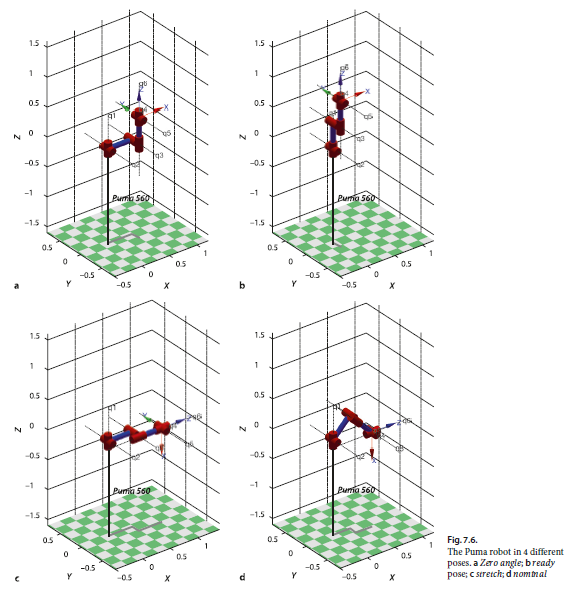

qr
qz
qn
qs

These poses could be used to quickly compute forward kinematics:

p560.fkine(qz)
p560.fkine(qn)

Similarly, it can be used to plot (run in command window):

p560.plot(qz)

## Lec 04.9 (Ch 7.2) - Base and Tool Transforms

Let's explore base and tool transform. 

Begin by importing a model of the puma 560:

mdl_puma560

Print the information of the robot by simply calling on the p560 variable name:

p560

Just to rehash, we can compute the forward kinematics easily with fkine. We also have some default joint angle configurations from the model that we can quickly use to compute the forward kinematics for that pose:

T=p560.fkine(qn)

#### **Analysis**

- Look at the coordinate frame in the plot. Does it correspond with the position you see in the forward kinematics?

T.t

- Does the orientation correspond to what you see in the forward kinematics?

T.R

Is it clear that the reference frame is the 0th link coordinate frame?

#### Visualization

If you cannot remember where the 0th link coordinate frame is

Note: Best if stacked alongside the command window.

p560.plot(qn, 'jvec')  % Best run in command window

### Base Transformation

Now that the actual p560 robot has a pedestal that we need to account for to get the correct pose of the starting robot link with respect to the **world**:

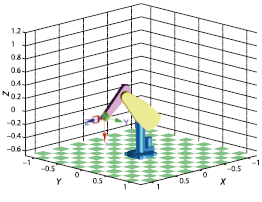

Every robot model has access to a member (or variable) called `base`. 

We can set `p560.base` to a particular transformation to correctly model the pose of the starting robot link wrt to the world. The pedestal is 75cm high directly above the {w} coordinate frame. Hence:

p560.base = SE3(0, 0, 0.75)

You can also see directly through the base member of the robot object:

p560.base

#### Forward Kinematic Computation

Once this has done, we can recompute the forward kinematics and see this shift reflected in the position of the end-effector pose {E} give the same joint configuration `qn` we used before.

Before running the  command, do a mental exercise and compute the position yourself:

p560.fkine(qn)

**Visualization**

You should still have your previous plot prior to the base transformation. 

We will call hold on and then replot the robot with the new base transformation at the qn configuration. 

You should see a sudeen change in the plot of the robot:

hold on
p560.plot(qn)  % Best run in command window

### Tool Transformation

In the same way we transformed the base, we can also transform the tool using the tool member:

p560.tool = transl(0.1,0,0)

Check the transformation:

p560.tool

#### Forward Kinematic Computation

And recompute the forward kinematics using the qn default joint angle configuration:

p560.fkine(qn)

#### Visualization

Once again, we will be intrested to visualize the F. Kin change given the plot of the previous transformation. 

(Given that the previous plot is plotted and stacked to the side), run the plot command.

You should see your end-effector adjust immediately:

p560.plot(qn) % Best run in command window

## Matlab Robotics System Toolbox

Matlab has a number of available modules as part of the Robotics and Autonomous Systems applications. There is a section dedicated to [Robotics and System Toolbox](https://www.mathworks.com/help/robotics/index.html?s_tid=CRUX_lftnav) and the [ROS Toolbox](https://www.mathworks.com/help/ros/index.html?s_tid=CRUX_lftnav). Both of these will be useful for the competition along with Peter Corke's toolbox. Often times functionality may overlap. 

The [**Robotics System Toolbox**](https://www.mathworks.com/help/robotics/index.html?s_tid=CRUX_lftnav) in turn has libraries that handlle robot modeling, inverse kinetmatics, motion and path planning, simulation, collision detection, and coordinate transformations. 

The robotics system toolbox in turn has libraries that support manipulator modeling. In this section we will cover main concepts. Below see screen shots of the 

[Robotics and Autonomous Systems](https://www.mathworks.com/help/overview/robotics-and-autonomous-systems.html?s_tid=CRUX_lftnav)

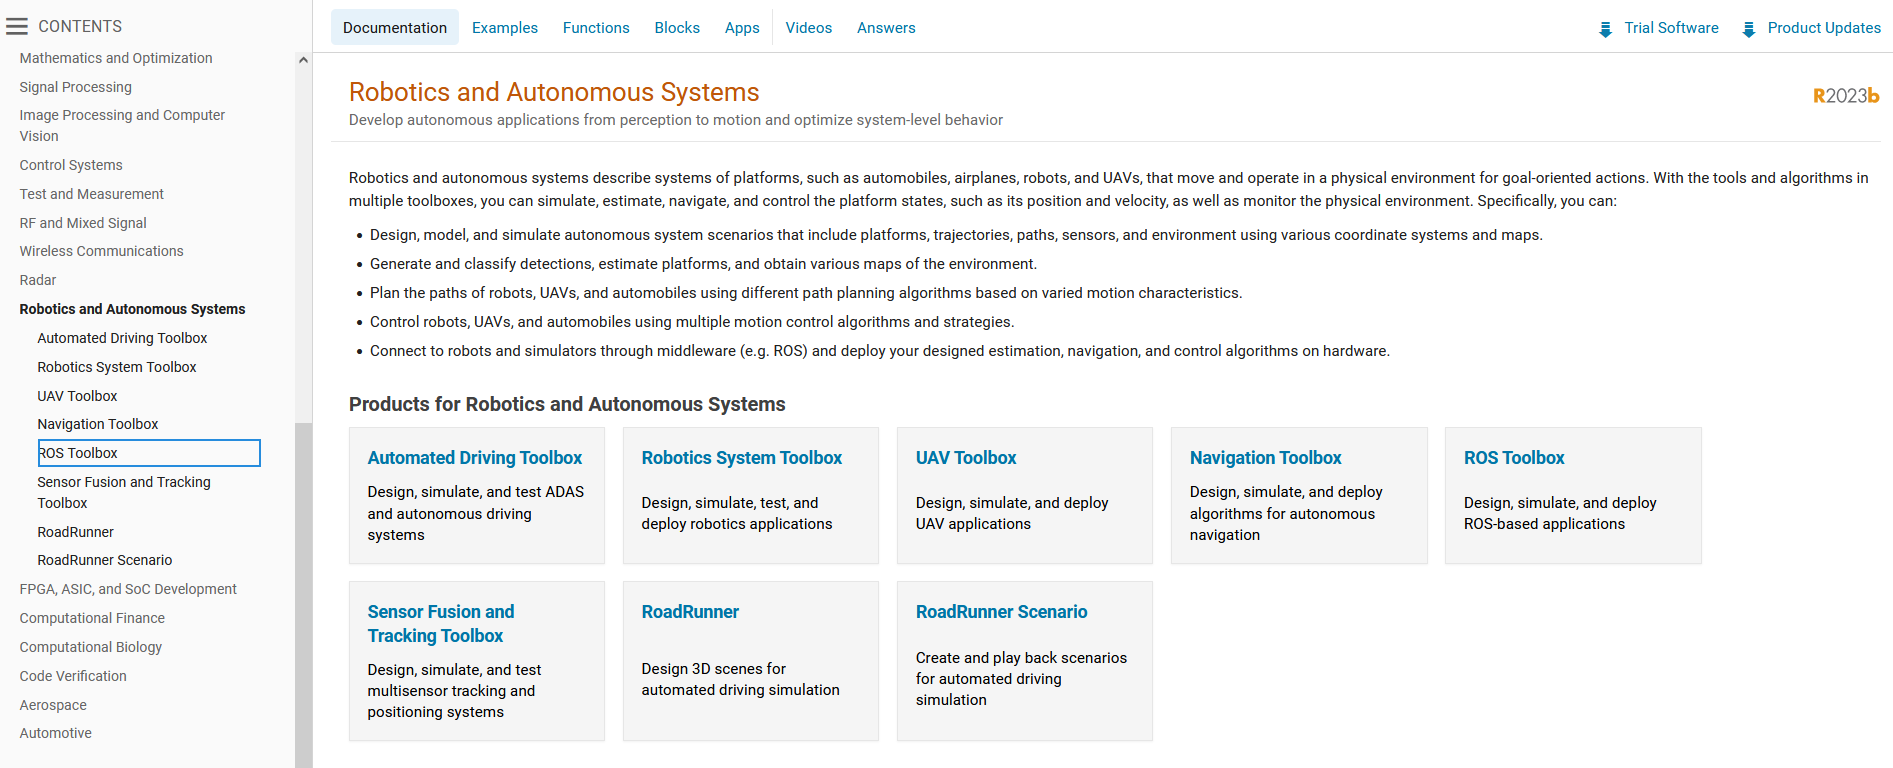

[Robotics System Toolbox](https://www.mathworks.com/help/robotics/index.html?s_tid=CRUX_lftnav)

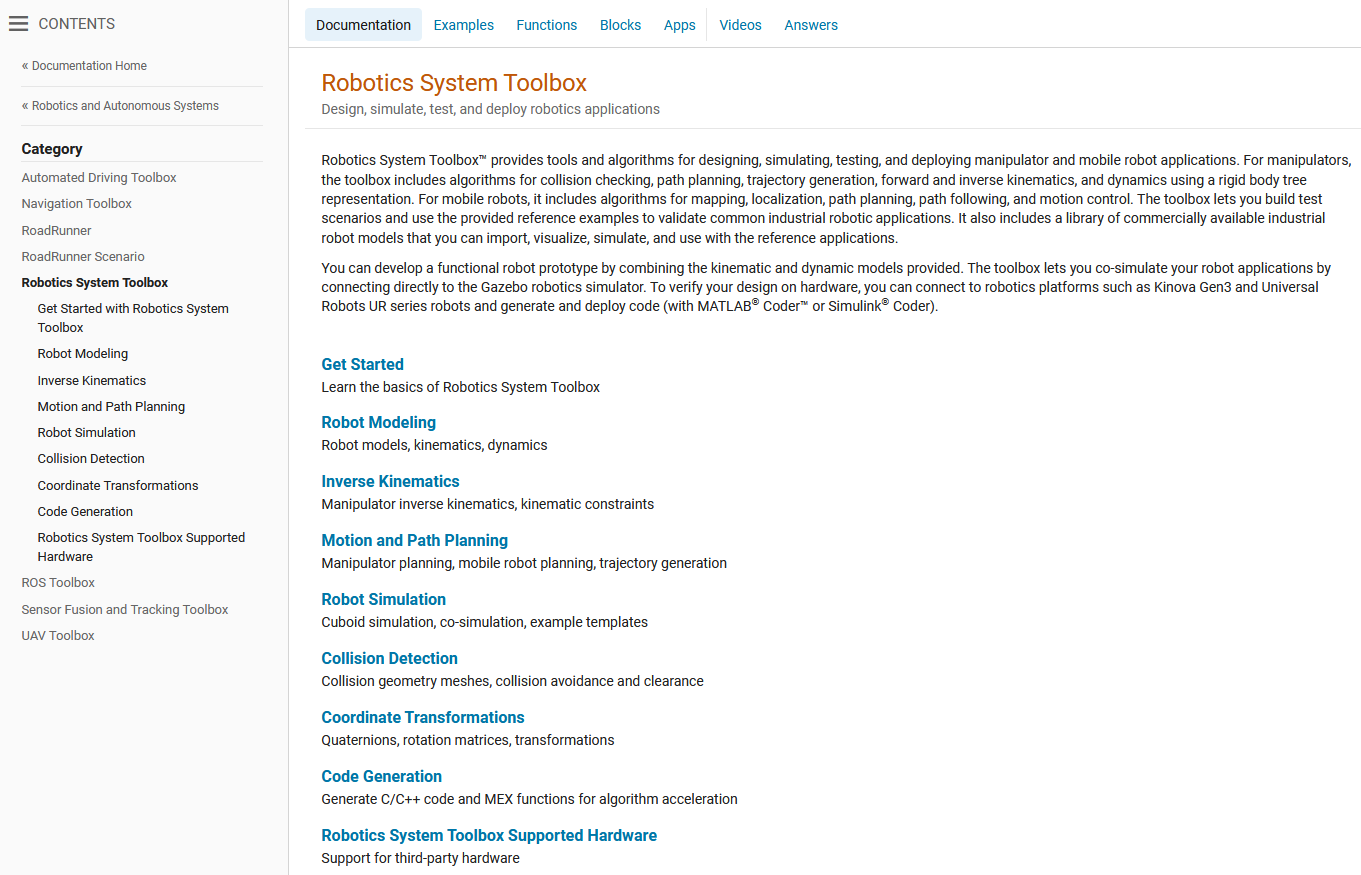

[Manipulator Modeling](https://www.mathworks.com/help/robotics/manipulator-modeling.html)

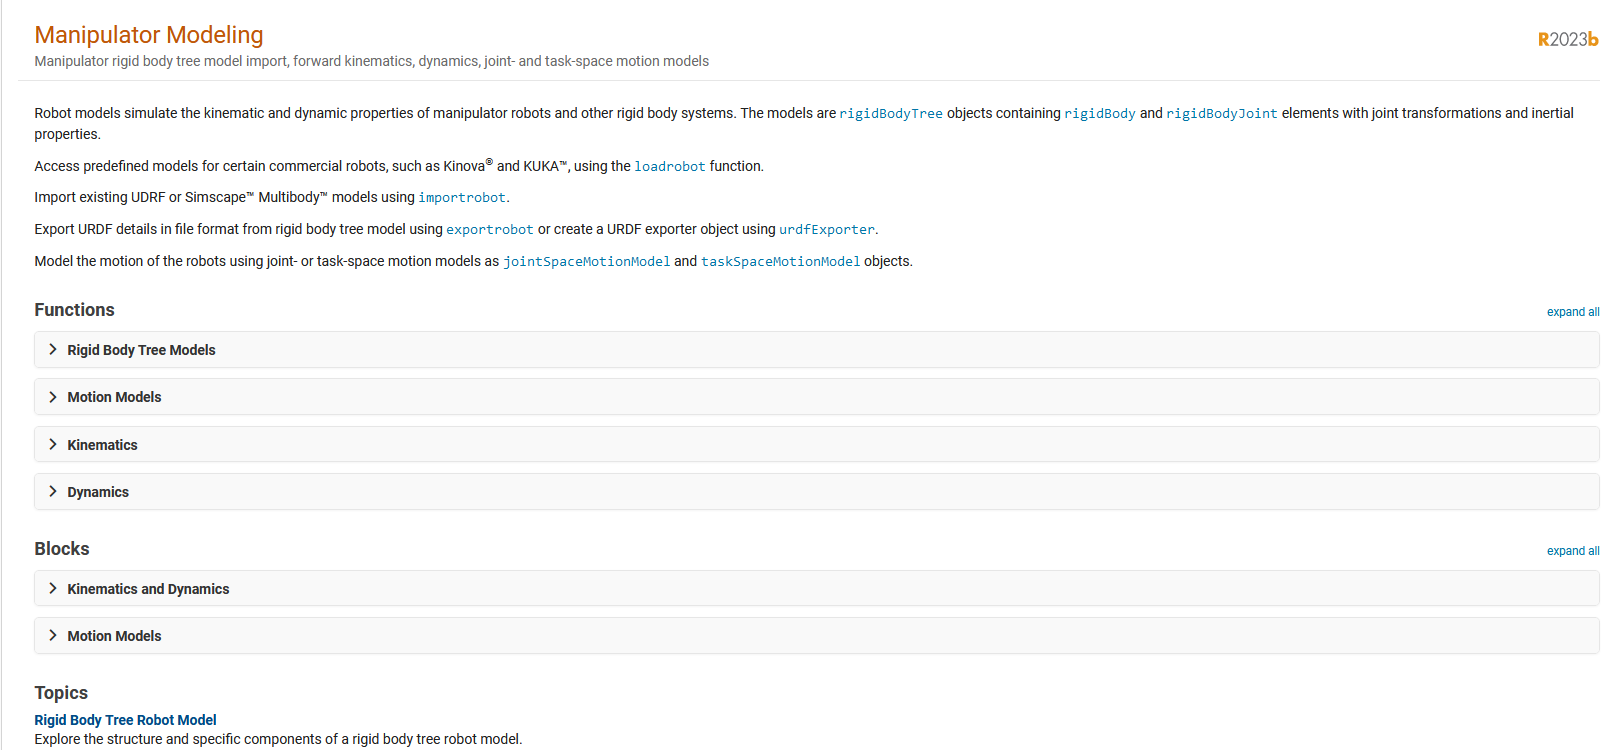

We previously explored the generation of a chain via ETS

import ETS2.*
a1 = 1; a2 = 1;
e = ETS2.Rz('q1')*ETS2.Tx(a1)*ETS2.Rz('q2')*ETS2.Tx(a2)
T = e.fkine(deg2rad([30 40]))

## **RVC3 7.1.2 Robots as Rigid Body Trees**

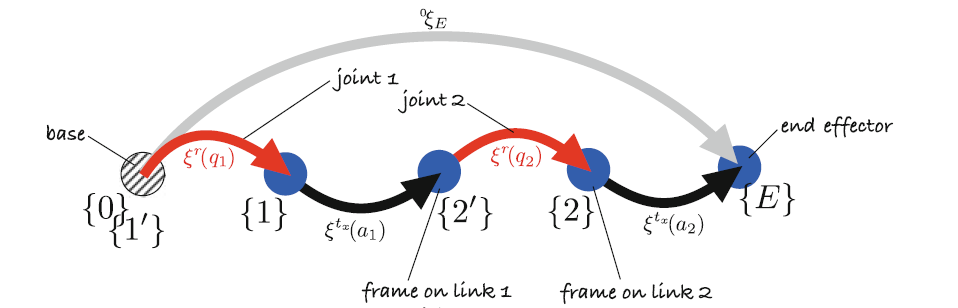

The above is a pose graph showing link coordinate frames. 

Each relative pose in this graph is a function of a joint variable. Frame {0} is the base which is fixed and frame {E} holds the end effector.

We now will focus on describing the robot as a **TREE** to represent its structure. Learn more about them [here](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html).

Trees will be known to have objects that will have parents and children (i.e. the parent of link1 will be link 0, the parent of link2 will be link1 and vice-versa).

- The main object to build a robot tree structure will be the [**rigidBodyTree**](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html)

- The tree will be made of [**rigidBody**](https://www.mathworks.com/help/robotics/ref/rigidbody.html) objects (i.e. the links of the robot) that will have properties such as mass, inertia, and collision geometries.

- Finally, each link will be contain a [**rigidBodyJoint**](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.html). It will define *how the link* moves relative to its parent.

The notion of **rigidBodyTree **is equivalent to the SerialLink we learned earlier but is used by the Matlab Robotics Toolbox.

## 7.1.2.2 2-Dimensional (Planar) Case

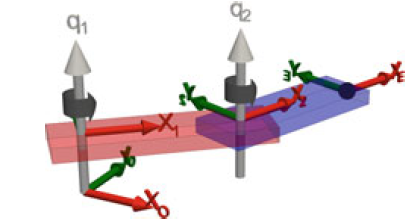

Coordinate frames are shown attached to the links of the robot about the joints. Link 1 is shown in red, and link 2 is in blue and the end-effector as a black ball.

The tree structure presents the notions of transformations in a slightly different language:

- A coordinate frame is attached rigidly to each link

- The pose of link 1 depends only on q1, while

- The pose of link 2 depends on q1+q2 and a1 and is visualized below:

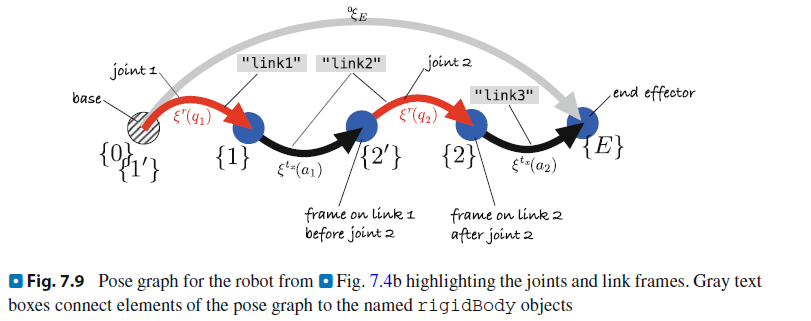

To build this robot we will have three kinds of operations:

- Create links via rigidBody

- Set the joint type for that link via rigidBodyJoint

- Set the position of the chid link via the transformation from parent to child

### 1. Links and Joints

Before we start, set the values of your link length paramters:

a1 = 1;
a2 = 1;

Now, create a link object via the rigidBody method (a rich class) with many properties. In particular, pay attention to its Joint member. 

link1 = rigidBody('link1')

Every link has a Joint member that is a structure with information about the joint in that link. 

See what this looks like:

link1.Joint

Let's change that joint from a 'fixed' type to a revolute type and see the updated information:

link1.Joint = rigidBodyJoint('joint1','revolute');
link1.Joint

We don't yet set a translation along the x-direction as we have been diong. We will create the 2nd link first and then set a transformation of link2 wrt to its parent link1. 

Create the link and joint type:

link2 = rigidBody("link2");
link2.Joint = rigidBodyJoint("joint2","revolute");

And finally, we will create a trivial link, link3, to compute transformations from the coordinate frame at the joint of link2 to the end-effector. By default it will use a 'Fixed Joint' and the transformation wrt parent is the identity transformation.

link3 = rigidBody("link3");

### 2. Set Transformations

Now we want to set the translations of the links along the x-axis. 

The transformation from the parent link to the child link is made *from the child Joint *object Ii.e. a **JointToParentTransform**). 

This is done via some homogeneous transformation operation (transl/trot).

- link2.object sets the transformation from link1 to link2; 

- link3.object (a null link) sets the transformation from link2 to link3). 

All of this is done via the [Joint.setFixedTransform()](http://joint.setfixedtransform%28%29https//www.mathworks.com/help/robotics/ref/rigidbodyjoint.setfixedtransform.html) method of the Joint class

See the help documentation for [Joint.setFixedTransform](http://joint.setfixedtransformhttps//www.mathworks.com/help/robotics/ref/rigidbodyjoint.setfixedtransform.html):

doc Joint.setFixedTransform

Set the transformation between link1 and link2:

Note: if a non-homogeneous transformation is desired, append option 'trvec':

link2.Joint.setFixedTransform(se3([a1 0 0],'trvec')); % Or link2.Joint.setFixedTransform(transl(a1,0,0));

Set the transformation between link2 and it's child (the trivial link3):

link3.Joint.setFixedTransform(se3([a2 0 0],'trvec'));

### 3. Robot Creation

We will now connect all of these links into a single chain and create our robot. 

We will do this via the **rigidBodyTree** method we introduced earlier. 

myRobot = rigidBodyTree(DataFormat="row");

Now add each of the three links via the **rigidBodyTree.addBody()** method, which takes 2 arguments:

- The rigid link object

- The name of the parent rigid link (often link.Name except for the first link which will be the base and is passed as **rigidBodyTree.BaseName**) as shown below:

myRobot.addBody(link1,myRobot.BaseName); % BaseName is 'base' by default
myRobot.addBody(link2,link1.Name);          
myRobot.addBody(link3,link2.Name);

Lear more about your robot via:

myRobot.showdetails

### Forward Kinematics

The forward kinematics can be called via the getTransform method and a row vector of joint angles along with the name of the end-effector frame ('link3' in this case):

T = myRobot.getTransform(deg2rad([30 40]),"link3")

It's even possible to compute the transformation between links:

myRobot.getTransform(deg2rad([0 30]),"link2","link1")

### Visualization

As we did earlier, we would like to visualize the pose of the robot at this joint angle configuration. We can do so using the **rigidBodyTree.show()** method along with a row vector of joint angles:

myRobot.show(deg2rad([30 40]));
view(0,90)

### Trajectory

It is also possible to show the robot arm moving through a series of joint angles as an animation. We can easily create a vector of joint angles that vary from 0 to pi in small increments via matlab's linspace:

q = [linspace(0,pi,100)' linspace(0,-2*pi,100)'];

Before we animate, we will set the update rate of the animation via rateControl and set it to 10Hz:

r = rateControl(10);

Finally, we can animate by calling rigidBodyTree.show() in a for loop across the joint increments vector. 

show() has an option called 'FastUpdate' which ensure that we only update the robot, not redrawing everythign at every step.

for i = 1:size(q,1)
    myRobot.show(q(i,:),FastUpdate=true,PreservePlot=false);
    r.waitfor;
end

## Robot Instrospection

Sometimes  you will want to study the physical properties of a robot you did not design. Most of the time this will be possible via the .Bodies() or .getBody() methods of the rigidBodyTree class.

link2 = myRobot.Bodies{2}

Or, 

link2 = myRobot.getBody("link2")

Given a rigidBody object like link2, you can explore it's parent or child:

parentLink = link2.Parent
childLink = link2.Children

Or it's type of link:

link2.Joint.Type

## 3D Robots

To create more advanced robots more quickly, we can use a method `ets2rbt `that maps ETS2 or ETS3 objects to a `rigidBodyTree` objects (composed of link and joint objects). 

Note:

For the chain multiplication, we will use ellipses (...) to continue code on another line:

a1 = 1; a2 = 1; % Links

robot6 = ets2rbt(ETS3.Rz("q1")*ETS3.Ry("q2")* ...
                 ETS3.Tz(a1)*ETS3.Ry("q3")*ETS3.Tz(a2)* ...
                 ETS3.Rz("q4")*ETS3.Ry("q5")*ETS3.Rz("q6"));

Let's look at the type of robot6:

class(robot6)

And we can also learn it's home position joint angle configuration:

robot6.homeConfiguration

## Robot Models

The matlab robot systems toolbox also has a database for a large number of robots. You can access them by the operation show below. Run in the command window:

loadrobot("<TAB>

#### Panda Robot

We can load the panda robot:

panda = loadrobot("frankaEmikaPanda",DataFormat="row");

panda.showdetails

Notice 

- this robot has a total of 11 links, 6 joints on the arm and two prismatic joints for the fingers.  

- panda_link8 and hand also have fixed joints which are not considered as joint angles. 

- you can click anywhere on the robot and see information about the particular link you clicked on.

#### **Forward Kinematics**

Now that you have a target joint angle configuration, you could get the transformation necesary to get there:

T = panda.getTransform(qr,"panda_hand");

#### Visualize

Before we start visualizing, let's create a joint configuration that gets the robot into a ready position:

qr = [0 -0.3 0 -2.2 0 2 0.7854 0 0];
panda.show(qr);

#### Generating Trajectories based on this interactive tool

Move the end-effector to a pose you would like to reach. Once you reach it, extract the joint angle configuration as follows:

clear
panda = loadrobot("frankaEmikaPanda",DataFormat="row");

Get this home/ready position configuration for the robot and store in `qr`:

qr = panda.homeConfiguration

Interact with the panda robot via **interactiveRigidBodyTree() **and move the robot to some interesting position, i.e. grabbing something from the floor.

intPanda = interactiveRigidBodyTree(panda,Configuration=qr)

When you are done, you can save that configuration to another joint variable (i.e. **q_joint_pick**) via calling intPanda.Configuration

q_joint_pick = intPanda.Configuration

You can move the arm from your current configuration to the target configuration in a smooth manner by using our old friend jtraj, which works well for joint configurations:

q = jtraj(qr,q_joint_pick,100);

Check the size of q:

size(q)

Finally play the trajectory via rateControl and the for loop as we did before, but this time using our trajectory points **q** and our **panda** robot:

r = rateControl(10); % Ensures for loop runs 10 cycles per second

for i = 1:size(q,1)
    panda.show( q(i,:),...
                FastUpdate=true, ...
                PreservePlot=false);
    r.waitfor;
end